clear;

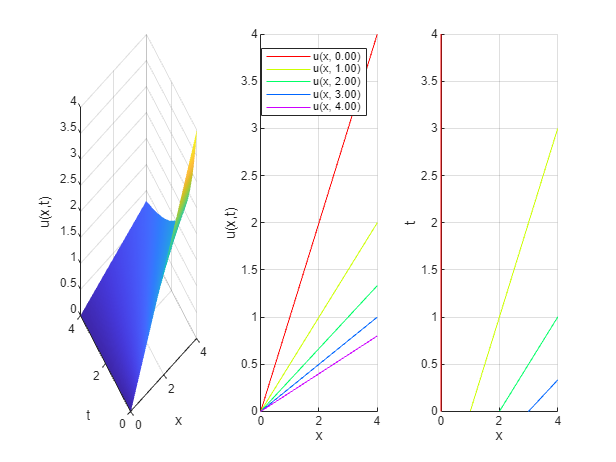

% u_t + u u_x = 0
% u(x,0) = x
% soln -> x/(t+1), for t>=0

u = @(x, t) x ./ (t+1);

N = 100;
xx = linspace(0, 4, N);
tt = linspace(0, 4, N);

PlotPDE(u, xx, tt, 5);

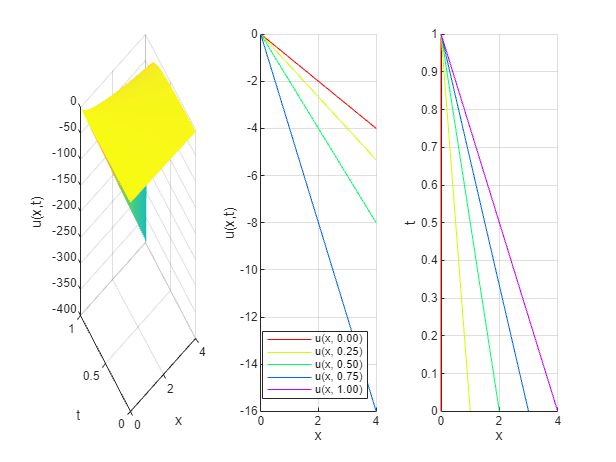

% u_t + u u_x = 0
% u(x,0) = x
% soln -> x/(t-1), for 0 <= t <1

u = @(x, t) x ./ (t-1);

N = 100;
xx = linspace(0, 4, N);
tt = linspace(0, 1, N);

PlotPDE(u, xx, tt, 5);

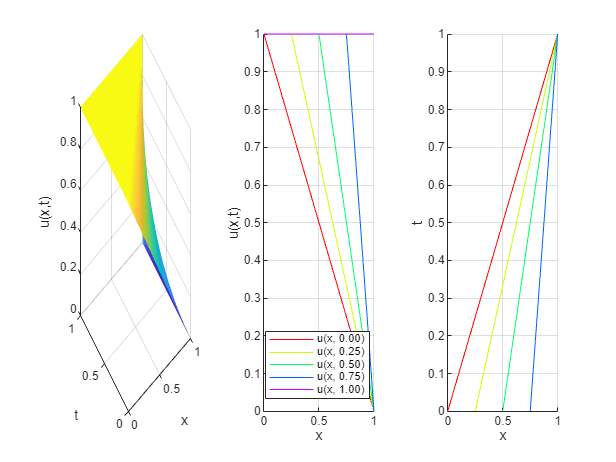

% u_t + u u_x = 0

syms u(x,t)
u(x,t) = piecewise(x <= t, 1, ...
                   (t<x)&(x<1), (1-x)/(1-t), ...
                   x >= 1, 0);

N = 100;
xx = linspace(0, 1, N);
tt = linspace(0, 1, N);

PlotPDE(u, xx, tt, 5);